## Assignment 7

### Part one

Task 1-2

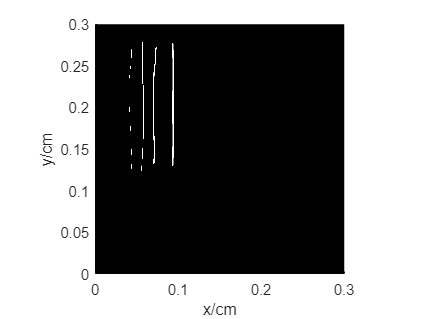

yaxis = linspace(0.3,0,30);
xaxis = linspace(0,0.3,30);
horizontals1 = showImage("hor_lines_bw.bmp",xaxis,yaxis);

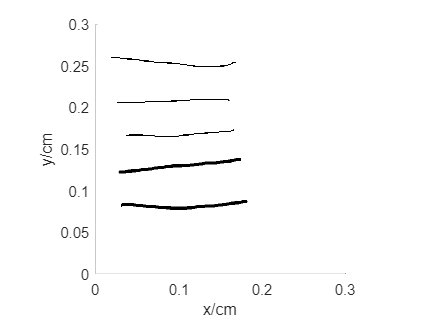

horizontals2 = showImage("hor_lines.bmp",xaxis,yaxis);

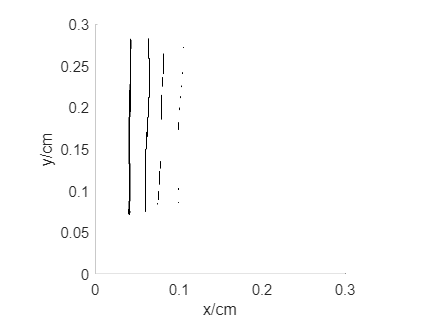

verticals1 = showImage("ver_lines.bmp",xaxis,yaxis);

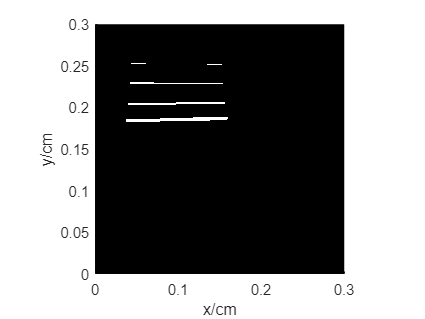

verticals2 = showImage("ver_lines_bw.bmp",xaxis,yaxis);

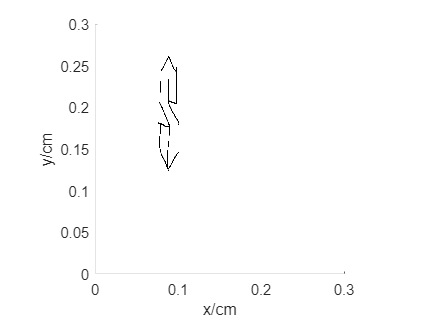

dollasign = showImage("dollasign.bmp",xaxis,yaxis);

Task 3

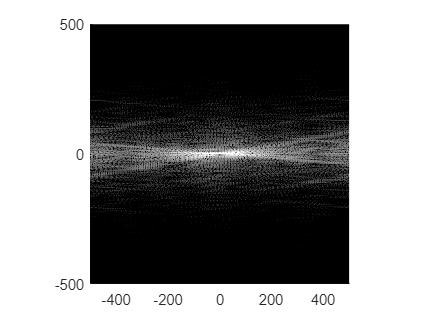

Nfft = 1024*2;
deltaX = 0.001;
deltaY = 0.001;



xfreqs = linspace(-0.5, 0.5, Nfft+1)*(1/deltaX);  xfreqs(end) = [];
yfreqs = linspace(-0.5, 0.5, Nfft+1)*(1/deltaY);  yfreqs(end) = [];
%figure();
%imshow(20*log10(abs(fft2(horizontals1))));

hor1fft = fft2d(horizontals1);
hor2fft = fft2d(horizontals2);
ver1fft = fft2d(verticals1);
ver2fft = fft2d(verticals2);
 
 
hor1fft_plot = fftimage(hor1fft,xfreqs,yfreqs);

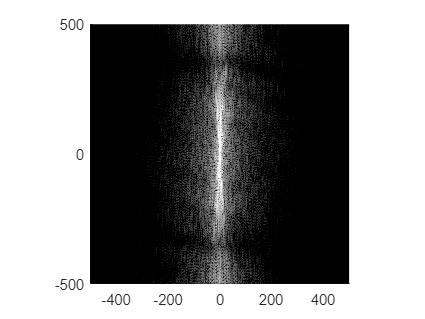

hor2fft_plot = fftimage(hor2fft,xfreqs,yfreqs);

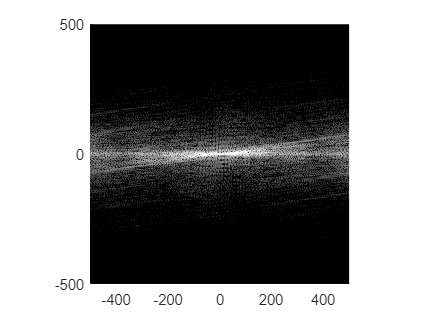

ver1fft_plot = fftimage(ver1fft,xfreqs,yfreqs);

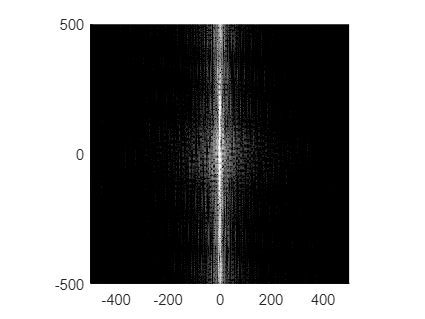

ver2fft_plot = fftimage(ver2fft,xfreqs,yfreqs);

Task 4

    a

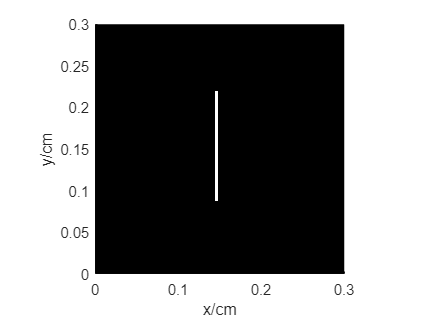

line = showImage('line.bmp',xaxis,yaxis);

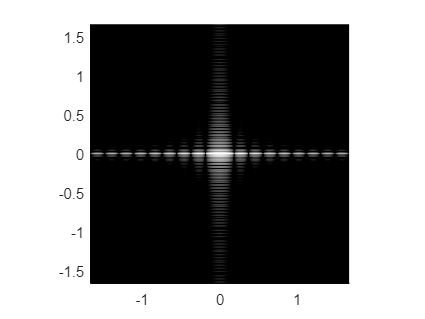

linefft = fft2d(line);
linefft_plot = fftimage(linefft,xfreqs,yfreqs);

As we see here, a vertical line will give a horisonal frequency spectre. We get some more on the horisontal this comes from the width

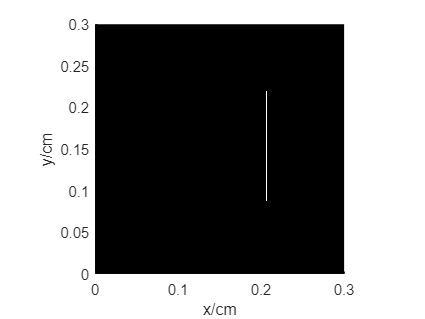


translated_line = imtranslate(line,[1000, 0],'OutputView','full');
translated_linefft = fft2d(translated_line);
figure();
imagesc('XData', xaxis, 'YData', yaxis,'CData',translated_line);
axis('image');
ylabel('y/cm');
xlabel('x/cm');
axis on;
colormap(gray(255));

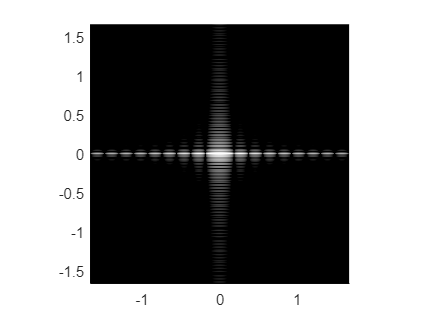

translated_linefft_plot = fftimage(translated_linefft,xfreqs,yfreqs);

As we see there will be no different when translating the images as the frequency will be the same. 

    b

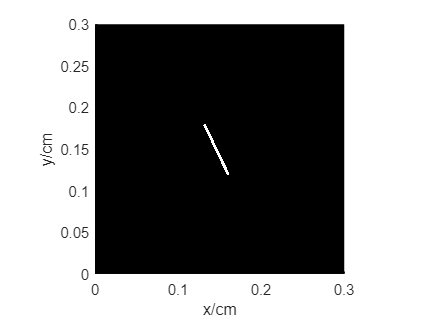

rotated_line = imrotate(line,30);
rotated_linefft = fft2d(rotated_line);
figure();
imagesc('XData', xaxis, 'YData', yaxis,'CData',rotated_line);
axis('image');
ylabel('y/cm');
xlabel('x/cm');
axis on;
colormap(gray(255));

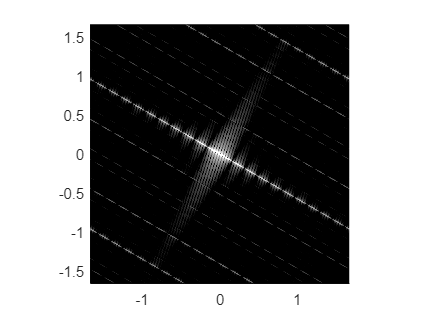

translated_linefft_plot = fftimage(rotated_linefft,xfreqs,yfreqs);

now we see that the frequency spectre is also rotated but inverse. 

    c

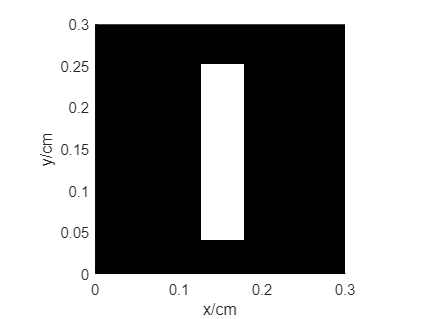

thick_line = showImage('thick_line.bmp',xaxis,yaxis);

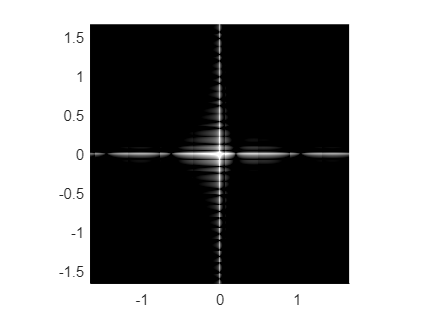

thick_linefft = fft2d(thick_line);
thick_linefft_plot = fftimage(thick_linefft,xfreqs,yfreqs);

As we have more width we get more frequency in the vertical axes also, but still we 

get the strongest horisontal frequencies. 

    d

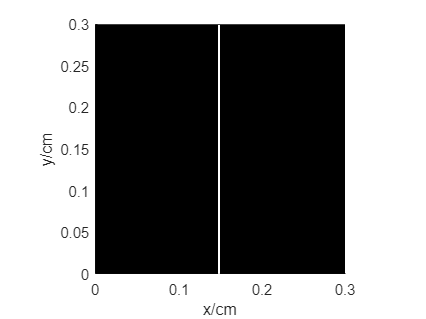


long_line = showImage('long_line.bmp',xaxis,yaxis);

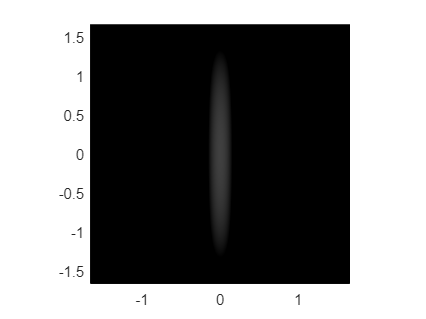

long_linefft = fft2d(long_line);
long_linefft_plot = fftimage(long_linefft,xfreqs,yfreqs);

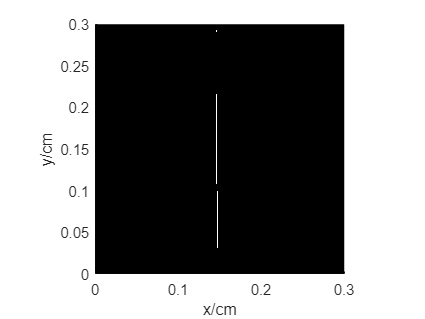


long_linev2 = showImage('longv2.bmp',xaxis,yaxis);

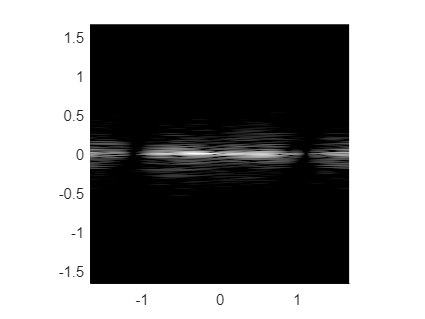

long_linefftv2 = fft2d(long_linev2);
long_linefft_plotv2 = fftimage(long_linefftv2,xfreqs,yfreqs);

In the first long line frequency spectre we see that its not correct. This could be because of that there is no edge at the top and bottom, so it cant "detect" any frequencies. The second line looks more correct, here we get smaller distances between the zeros compared to the shorter line (the space is because of the space in the drawn image, wasnt there in paint). 

Problem 2

    Task 1

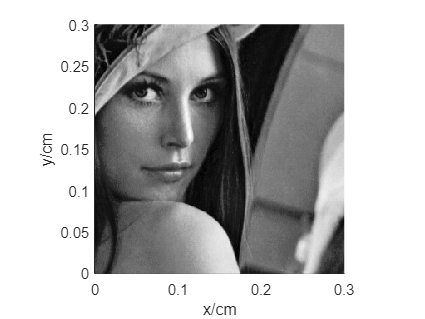

lena = showImage('lena.jpg', xaxis,yaxis);

    Task 2

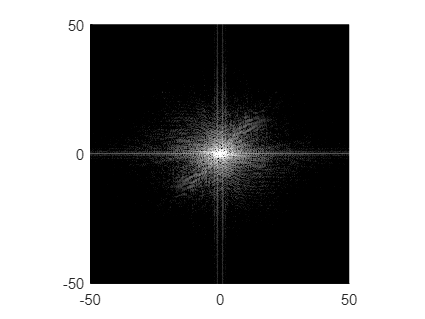

lena_fft = fft2d(lena);
lena_fft_plot = fftimage(lena_fft,xfreqs,yfreqs);

function image = showImage(path,x,y)
    image  = im2double(imread(path));
    image = image(:,:,1);
    figure();
    imagesc('XData', x, 'YData', y,'CData',image);
    axis('image');
    ylabel('y/cm');
    xlabel('x/cm');
    axis on;
    colormap(gray(255))
end

function res = fft2d(image)
    res = fft2(image);
    res = fftshift(res);
end
function im = fftimage(res,xfreqs,yfreqs)
    fft_image = 20*log10(abs(res));
    figure();
    im = imagesc('XData', xfreqs, 'YData', yfreqs,'CData',fft_image);
    axis('image');
    dyn = 40;
    gain = -60;
    caxis([-dyn 0]-gain)
    colormap(gray(255));

end
